clear all, close all, clc

%importing data


folderPaths = {'D:\IITK\Projects\Prof Mittal\New experiment\00_Shuttlecock_Aarush\Write\Bal_Natural Frequency Data\NF_WithSting', 'D:\IITK\Projects\Prof Mittal\New experiment\00_Shuttlecock_Aarush\Write\Bal_Natural Frequency Data\SF_WithSting','D:\IITK\Projects\Prof Mittal\New experiment\00_Shuttlecock_Aarush\Write\Bal_Natural Frequency Data\NF_WithoutSting','D:\IITK\Projects\Prof Mittal\New experiment\00_Shuttlecock_Aarush\Write\Bal_Natural Frequency Data\SF_WithoutSting'};
data = cell(43, 2);
count =1;
for folderIdx = 1:numel(folderPaths)
    subfolderPath = folderPaths{folderIdx};
    if folderIdx >2
        ext = '*.dat';
    else 
         ext = '*.txt';
    end

    files = dir(fullfile(subfolderPath, ext));
    % Initialize a cell array to store the data from each file
    
    % Loop through each .dat file
    for fileIdx = 1:numel(files)
        filePath = fullfile(subfolderPath, files(fileIdx).name);
        
        % Read the data from the current file
        fileData = importdata(filePath); % You can use load() or other appropriate functions based on your data format
 
        % Store the data and file name in the cell array
        data{count, 1} =  files(fileIdx).name ; % File name
        data{count, 2} = fileData; % Imported data
        count = count+1;
    end
end

col1 = {'NF_WithSting', 'SF_WithSting','NF_WithoutSting','SF_WithoutSting'};
col2 = {'Ax','N','S','Rm','Pm','Ym','Resu'};

NF_WithSting1 = cell2mat(data(1,2));
for k = 2:4
    NF_WithSting1 = [NF_WithSting1 cell2mat(data(k,2))];
end
NF_WithSting2 = cell2mat(data(5,2));
for k = 6:8
    NF_WithSting2 = [NF_WithSting2 cell2mat(data(k,2))];
end
SF_WithSting1 = cell2mat(data(9,2));
for k = 10:16
    SF_WithSting1 = [SF_WithSting1 cell2mat(data(k,2))];
end
SF_WithSting2 = cell2mat(data(17,2));
for k = 18:24
    SF_WithSting2 = [SF_WithSting2 cell2mat(data(k,2))];
end
NF_WithSting1 = Bal_load2coeff(NF_WithSting1);
NF_WithSting2 = Bal_load2coeff(NF_WithSting2);
SF_WithSting1 = Bal_load2coeff(SF_WithSting1);
SF_WithSting2 = Bal_load2coeff(SF_WithSting2);

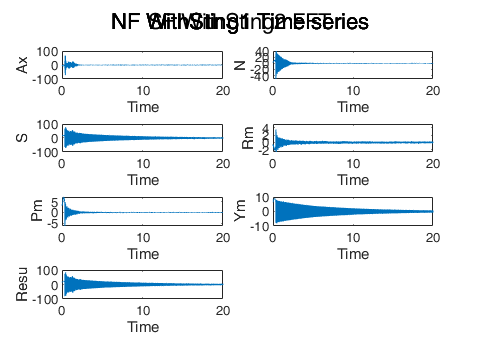

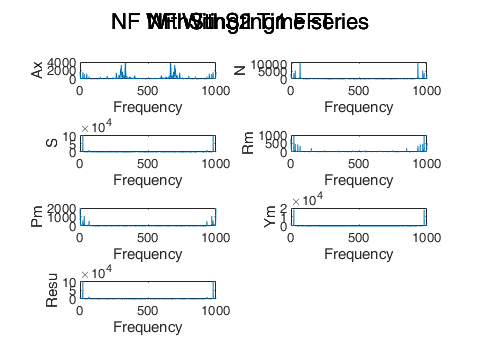

Imagefolder = 'D:\IITK\Projects\Prof Mittal\New experiment\00_Shuttlecock_Aarush\Write\Bal_Natural Frequency Data\Plot';
fftplotbal_all(NF_WithSting1(:,1:20000),col2,"NF WithSting1",Imagefolder);

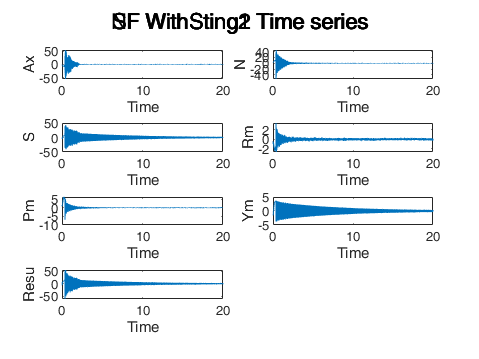

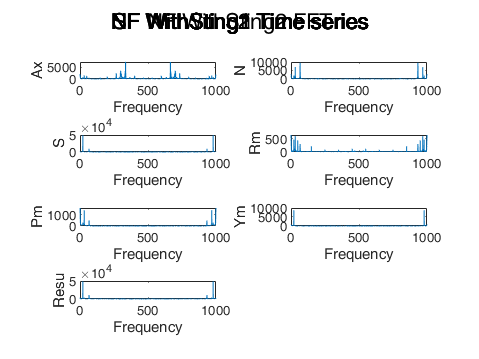

fftplotbal_all(NF_WithSting2(:,1:20000),col2,"NF WithSting2",Imagefolder);

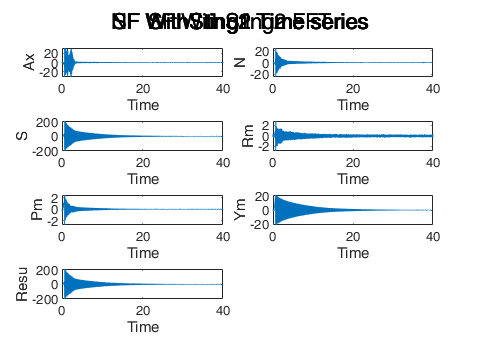

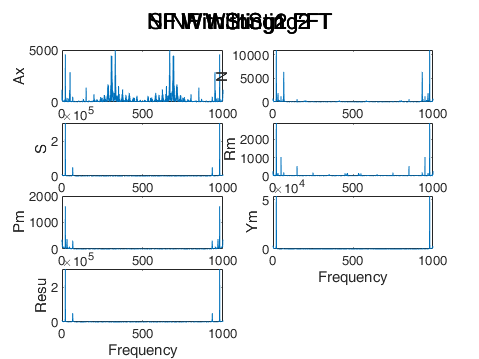

%second data seems good
fftplotbal_all(SF_WithSting1(:,1:40000),col2,"SF WithSting1",Imagefolder);

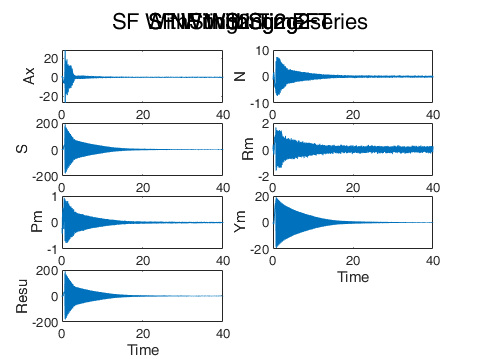

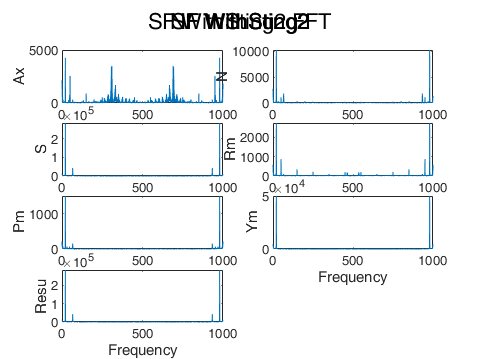

fftplotbal_all(SF_WithSting2(:,1:40000),col2,"SF WithSting2",Imagefolder);

%second data seems good

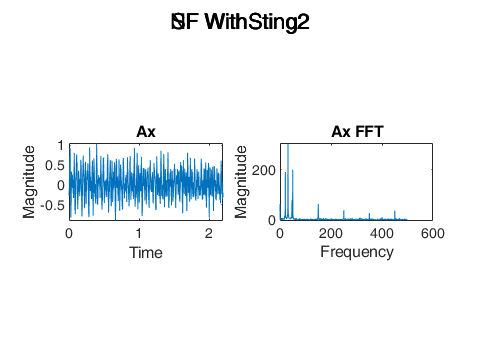

%plotting for the NF
NF_WithSting2_peaks = cell(7, 2);
[a b] = fftplotbal_single(NF_WithSting2(:,2800:5*1000),1,"NF WithSting2");

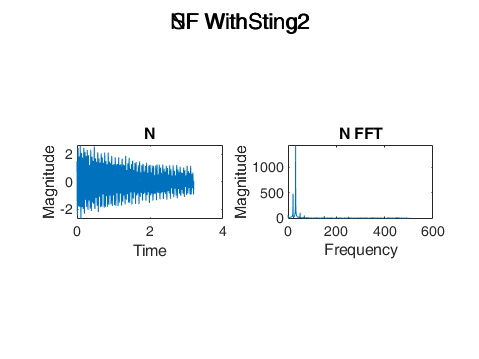

NF_WithSting2_peaks{1,1} = a;
NF_WithSting2_peaks{1,2} = b;
[a b] = fftplotbal_single(NF_WithSting2(:,2800:6*1000),2,"NF WithSting2");

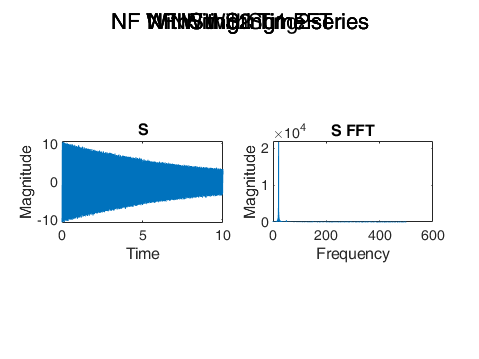

NF_WithSting2_peaks{2,1} = a;
NF_WithSting2_peaks{2,2} = b;
[a b] = fftplotbal_single(NF_WithSting2(:,5*1000:15*1000),3,"NF WithSting2");

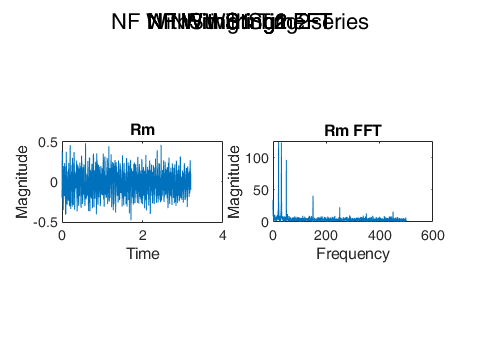

NF_WithSting2_peaks{3,1} = a;
NF_WithSting2_peaks{3,2} = b;
[a b] = fftplotbal_single(NF_WithSting2(:,2800:6*1000),4,"NF WithSting2");

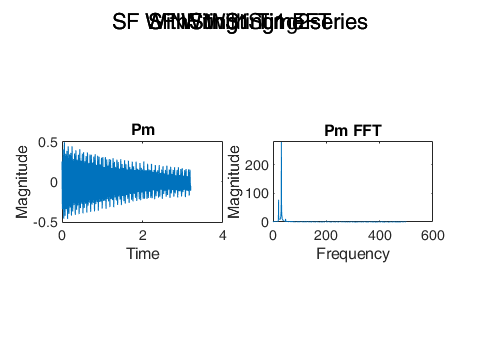

NF_WithSting2_peaks{4,1} = a;
NF_WithSting2_peaks{4,2} = b;
[a b] = fftplotbal_single(NF_WithSting2(:,2800:6*1000),5,"NF WithSting2");

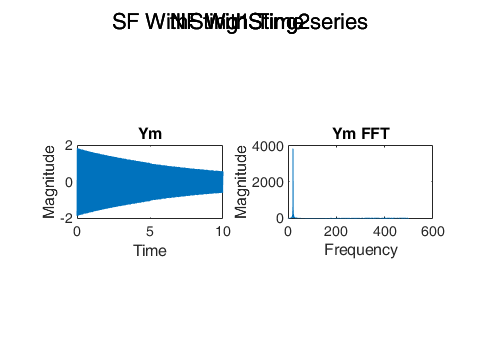

NF_WithSting2_peaks{5,1} = a;
NF_WithSting2_peaks{5,2} = b;
[a b] = fftplotbal_single(NF_WithSting2(:,5*1000:15*1000),6,"NF WithSting2");

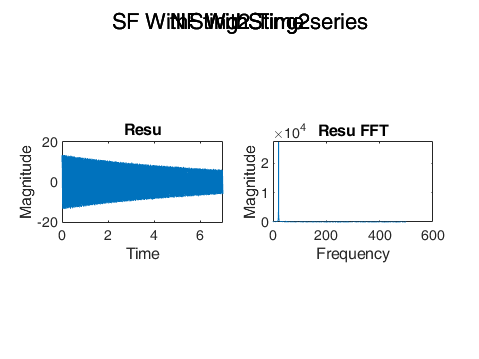

NF_WithSting2_peaks{6,1} = a;
NF_WithSting2_peaks{6,2} = b;
[a b] = fftplotbal_single(NF_WithSting2(:,3*1000:10*1000),7,"NF WithSting2");

NF_WithSting2_peaks{7,1} = a;
NF_WithSting2_peaks{7,2} = b;
save('NF_WithSting2_peaks.mat', 'NF_WithSting2_peaks');

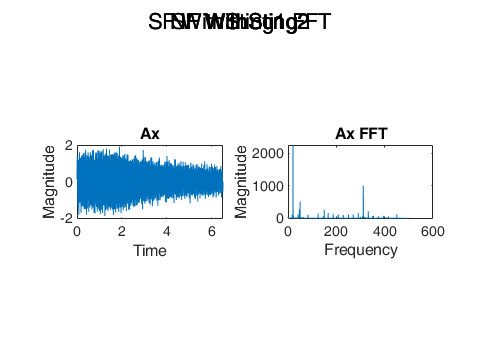

%plotting for the SF
SF_WithSting2_peaks = cell(7, 2);
[c d] = fftplotbal_single(SF_WithSting2(:,3.5*1000:10*1000),1,"SF WithSting2");

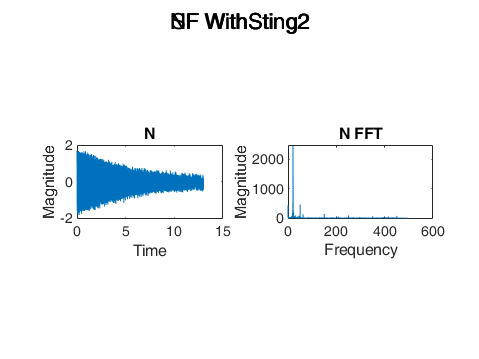

SF_WithSting2_peaks{1,1} = c;
SF_WithSting2_peaks{1,2} = d;
[c d] = fftplotbal_single(SF_WithSting2(:,7*1000:20*1000),2,"SF WithSting2");

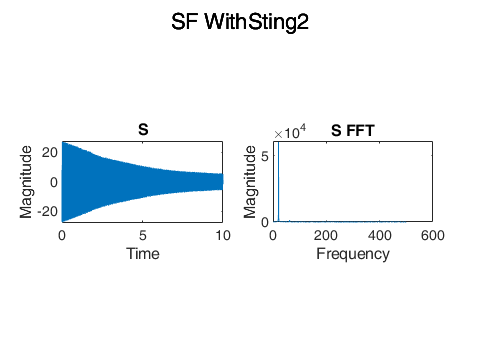

SF_WithSting2_peaks{2,1} = c;
SF_WithSting2_peaks{2,2} = d;
[c d] = fftplotbal_single(SF_WithSting2(:,10*1000:20*1000),3,"SF WithSting2");

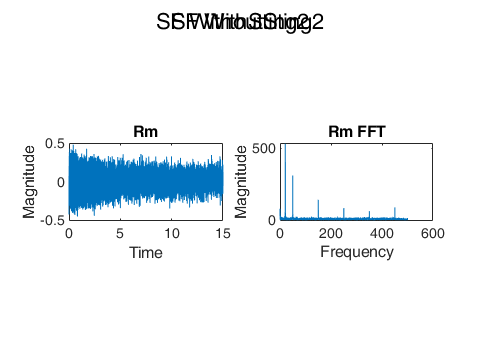

SF_WithSting2_peaks{3,1} = c;
SF_WithSting2_peaks{3,2} = d;
[c d] = fftplotbal_single(SF_WithSting2(:,10*1000:25*1000),4,"SF WithSting2");

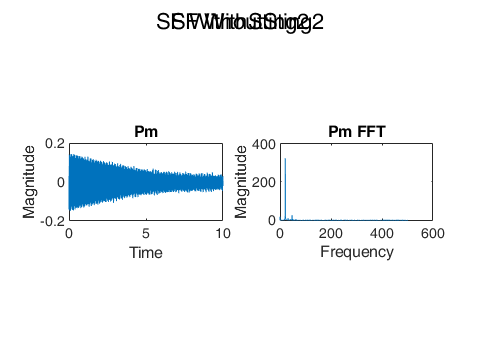

SF_WithSting2_peaks{4,1} = c;
SF_WithSting2_peaks{4,2} = d;
[c d] = fftplotbal_single(SF_WithSting2(:,10*1000:20*1000),5,"SF WithSting2");

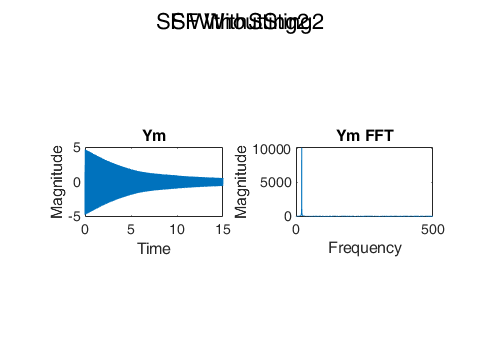

SF_WithSting2_peaks{5,1} = c;
SF_WithSting2_peaks{5,2} = d;
[c d] = fftplotbal_single(SF_WithSting2(:,10*1000:25*1000),6,"SF WithSting2");

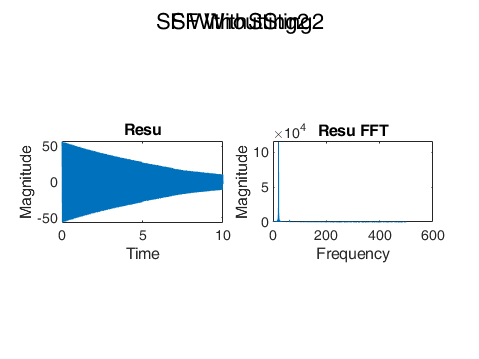

SF_WithSting2_peaks{6,1} = c;
SF_WithSting2_peaks{6,2} = d;
[c d] = fftplotbal_single(SF_WithSting2(:,5*1000:15*1000),7,"SF WithSting2");

SF_WithSting2_peaks{7,1} = c;
SF_WithSting2_peaks{7,2} = d;
save('SF_WithSting2_peaks.mat', 'SF_WithSting2_peaks');

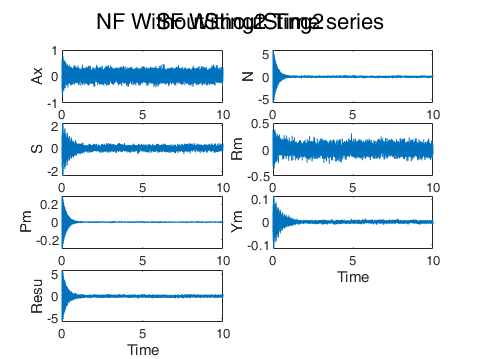

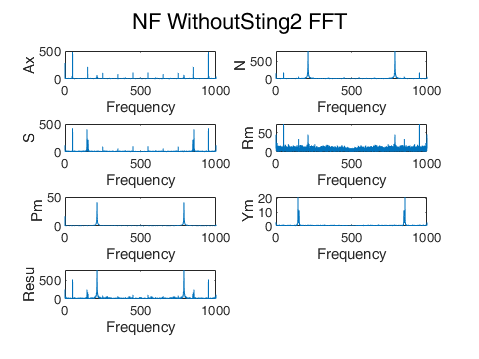

%without sting 


% for k = 24:43
%     pp = Bal_load2coeff(cell2mat(data(k,2)));
%     for j = 2:3
%         figure()
%         plot(pp(j,:))
%         title(k + " " + j)
%     end
% end

%for without sting data 27 seems to be better for NF without sting 
%for without sting data 38 seems to be better for SF without sting

NF_WithoutSting2 = Bal_load2coeff(cell2mat(data(27,2)));
SF_WithoutSting2 = Bal_load2coeff(cell2mat(data(38,2)));
fftplotbal_all(NF_WithoutSting2,col2,"NF WithoutSting2",Imagefolder);

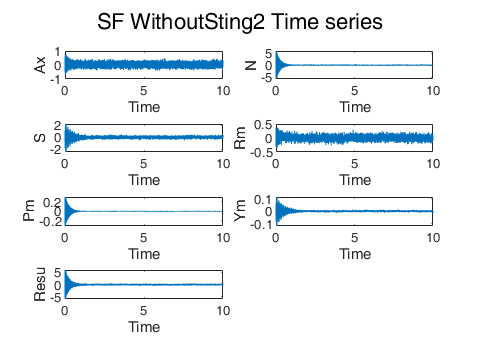

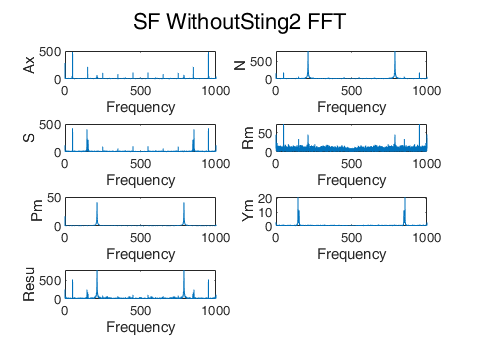

fftplotbal_all(NF_WithoutSting2,col2,"SF WithoutSting2",Imagefolder);

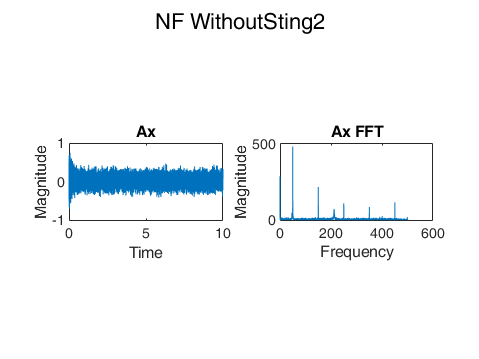

%plotting for the NF
NF_WithoutSting2_peaks = cell(7, 2);
[a b] = fftplotbal_single(NF_WithoutSting2,1,"NF WithoutSting2");

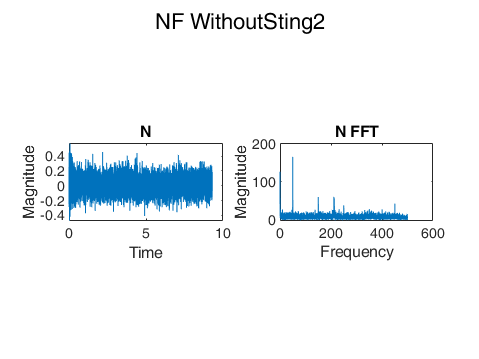

NF_WithoutSting2_peaks{1,1} = a;
NF_WithoutSting2_peaks{1,2} = b;
[a b] = fftplotbal_single(NF_WithoutSting2(:,0.7*1000:10*1000),2,"NF WithoutSting2");

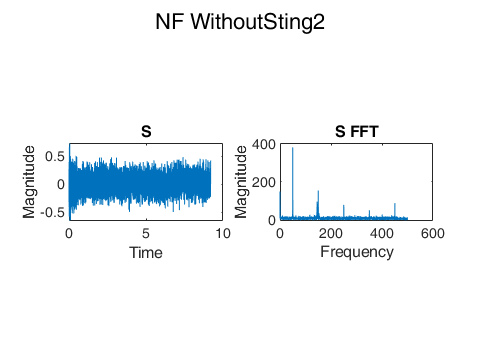

NF_WithoutSting2_peaks{2,1} = a;
NF_WithoutSting2_peaks{2,2} = b;
[a b] = fftplotbal_single(NF_WithoutSting2(:,0.8*1000:10*1000),3,"NF WithoutSting2");

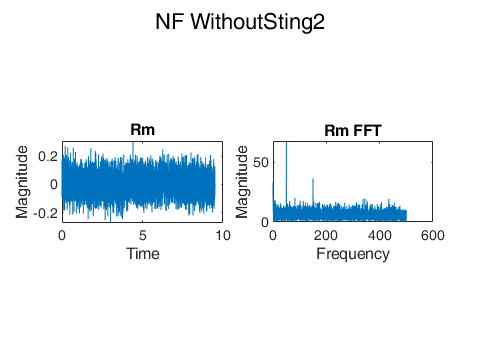

NF_WithoutSting2_peaks{3,1} = a;
NF_WithoutSting2_peaks{3,2} = b;
[a b] = fftplotbal_single(NF_WithoutSting2(:,0.5*1000:10*1000),4,"NF WithoutSting2");

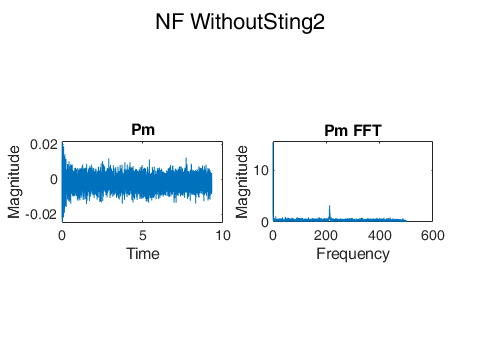

NF_WithoutSting2_peaks{4,1} = a;
NF_WithoutSting2_peaks{4,2} = b;
[a b] = fftplotbal_single(NF_WithoutSting2(:,0.7*1000:10*1000),5,"NF WithoutSting2");

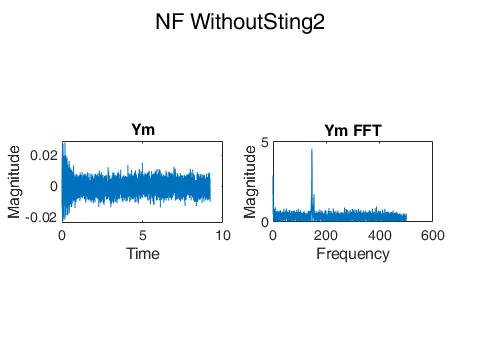

NF_WithoutSting2_peaks{5,1} = a;
NF_WithoutSting2_peaks{5,2} = b;
[a b] = fftplotbal_single(NF_WithoutSting2(:,0.8*1000:10*1000),6,"NF WithoutSting2");

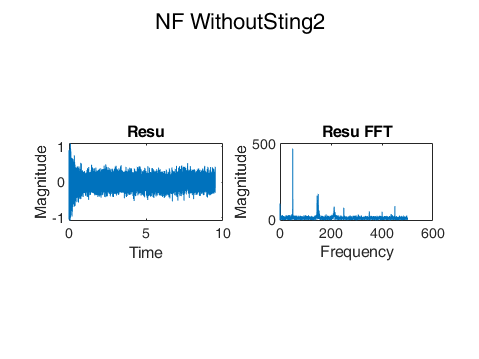

NF_WithoutSting2_peaks{6,1} = a;
NF_WithoutSting2_peaks{6,2} = b;
[a b] = fftplotbal_single(NF_WithoutSting2(:,0.5*1000:10*1000),7,"NF WithoutSting2");

NF_WithoutSting2_peaks{7,1} = a;
NF_WithoutSting2_peaks{7,2} = b;
save('NF_WithoutSting2_peaks.mat', 'NF_WithoutSting2_peaks');


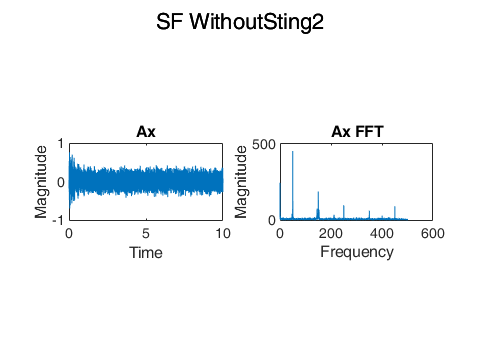

%plotting for the SF
SF_WithoutSting2_peaks = cell(7, 2);
[c d] = fftplotbal_single(SF_WithoutSting2,1,"SF WithoutSting2");

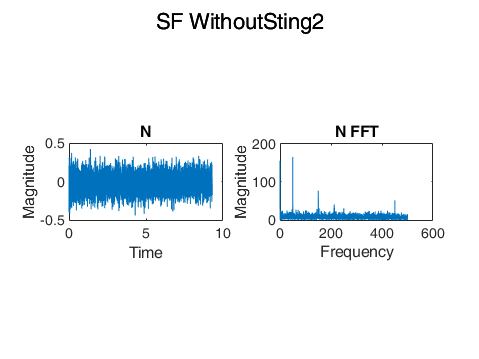

SF_WithoutSting2_peaks{1,1} = c;
SF_WithoutSting2_peaks{1,2} = d;
[c d] = fftplotbal_single(SF_WithoutSting2(:,0.7*1000:10*1000),2,"SF WithoutSting2");

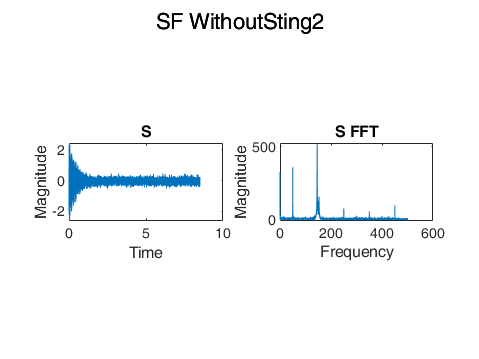

SF_WithoutSting2_peaks{2,1} = c;
SF_WithoutSting2_peaks{2,2} = d;
[c d] = fftplotbal_single(SF_WithoutSting2(:,1.5*1000:10*1000),3,"SF WithoutSting2");

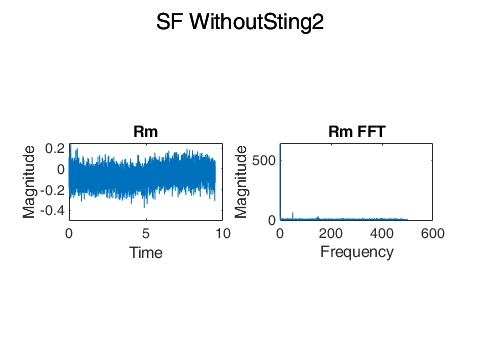

SF_WithoutSting2_peaks{3,1} = c;
SF_WithoutSting2_peaks{3,2} = d;
[c d] = fftplotbal_single(SF_WithoutSting2(:,0.5*1000:10*1000),4,"SF WithoutSting2");

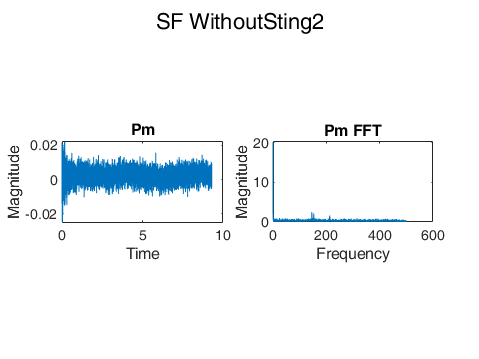

SF_WithoutSting2_peaks{4,1} = c;
SF_WithoutSting2_peaks{4,2} = d;
[c d] = fftplotbal_single(SF_WithoutSting2(:,0.7*1000:10*1000),5,"SF WithoutSting2");

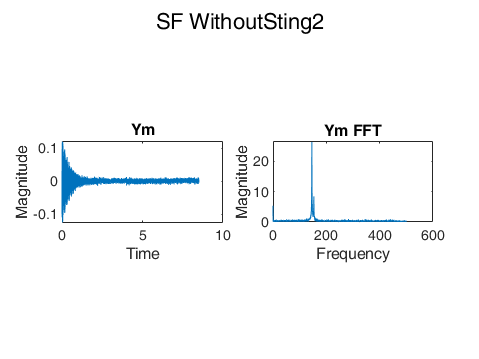

SF_WithoutSting2_peaks{5,1} = c;
SF_WithoutSting2_peaks{5,2} = d;
[c d] = fftplotbal_single(SF_WithoutSting2(:,1.5*1000:10*1000),6,"SF WithoutSting2");

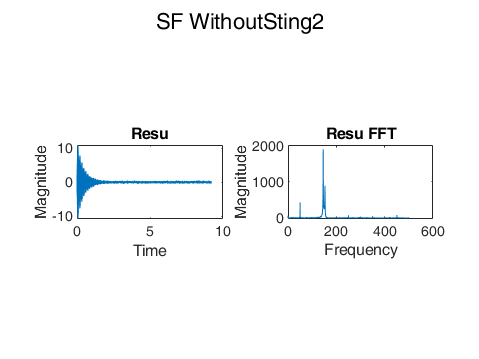

SF_WithoutSting2_peaks{6,1} = c;
SF_WithoutSting2_peaks{6,2} = d;
[c d] = fftplotbal_single(SF_WithoutSting2(:,0.8*1000:10*1000),7,"SF WithoutSting2");

SF_WithoutSting2_peaks{7,1} = c;
SF_WithoutSting2_peaks{7,2} = d;
save('SF_WithoutSting2_peaks.mat', 'SF_WithoutSting2_peaks');